Description:

To run the Cobra toolbox you need first to download the repository as indicated [at this link](https://opencobra.github.io/cobratoolbox/stable/installation.html). Your cobra folder should be included within the file code.

clc;
clear all;
close all;

%Paremeters
fontsize=15;%for plotting

%including all parent folders up to the file 'code', this makes visible all
%files within this code, which includes the COBRA toolbox you need first to
%download as follows from the intr
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\bioelectrodynamics\code



initCobraToolbox(false) % false, as we don't want to update



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2025
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.49.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

%This lists all the versions of functions named initCobraToolbox in your matlab installation, after the current path, the version used is the first in this list.
which -all initCobraToolbox

D:\code\bioelectrodynamics\code\NN\cobratoolbox~\initCobraToolbox.m


**Placing the folder with the mat file and loading the model**

% Specify the MAT file you're looking for
% matFileName = 'model_aux.mat';
% matFileName = 'iMM904.mat';
matFileName = 'model_yeastGEM_v9_0_2.mat';
%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\bioelectrodynamics\code


%place the current Matlab folder with the project files
cd(fileparts(which(matFileName)));
%load the model
model=readCbModel(matFileName);

Each model.subSystems{x} has been changed to a character array.


### Inspecting the model

% default constraints on the model
printConstraints(model,-1000,1000)

    Closed_reaction               Name                lb    ub                    equation                
    _______________    ___________________________    __    __    ________________________________________

      {'r_0217'}       {'aspartate transaminase' }    0     0     {'s_0993 + s_1273  -> s_0182 + s_0975 '}
      {'r_0312'}       {'cysteine synthase'      }    0     0     {'s_0841 + s_1234  -> s_0362 + s_0981 '}
      {'r_1250'}       {'putrescine excretion'   }    0     0     {'s_1389  -> s_1390 '                  }
      {'r_1259'}       {'spermidine excretion'   }    0     0     {'s_1439  -> s_1440 '                  }
      {'r_1663'}       {'bicarbonate exchange'   }    0     0     {'s_0446  -> '                         }
      {'r_4062'}       {'lipid backbone exchange'}    0     0     {'s_3746  -> '

% By convention, the number of rows in S is equal to the 
% number of metabolites, and number of columns is equal to the 
% number of reactions:
[nMets,nRxns] = size(model.S);
disp(['Number of metabolites: ',num2str(nMets)])

Number of metabolites: 2806


disp(['Number of reactions: ',num2str(nRxns)])

Number of reactions: 4131


#### **Visualization of the S matrix**

**Description:** The Yeast cell model S matrix can be visualized by using the spy command in Matlab. This command will represent all non-zero entries in S with a dot

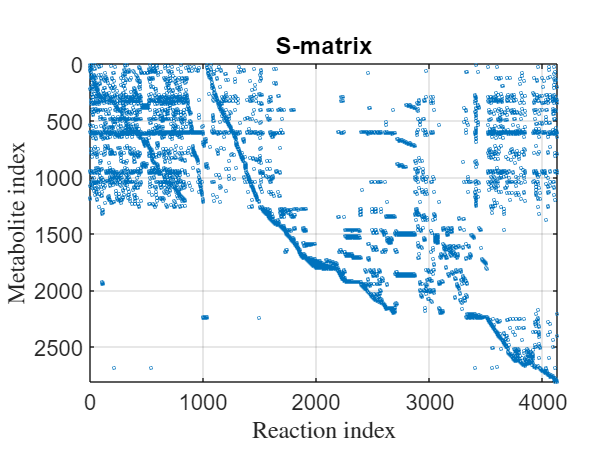

figure;
spy(model.S,'o',2); grid on;
xlabel('Reaction index','Interpreter','latex');
ylabel('Metabolite index','Interpreter','latex');
title('S-matrix')
set(gca,'FontSize',fontsize);

#### **Number of reactions the metabolites occur in**

**Description:** The S matrix can be converted into a binary matrix (Sbin), by replacing all non-zero elements in S with a ‘1’ in Sbin. Then, all ones in each row of the Sbin can be summed to determine the number of reactions a metabolite occurs in.  The full code to binarize the S matrix and calculate and plot metabolite connectivity is:

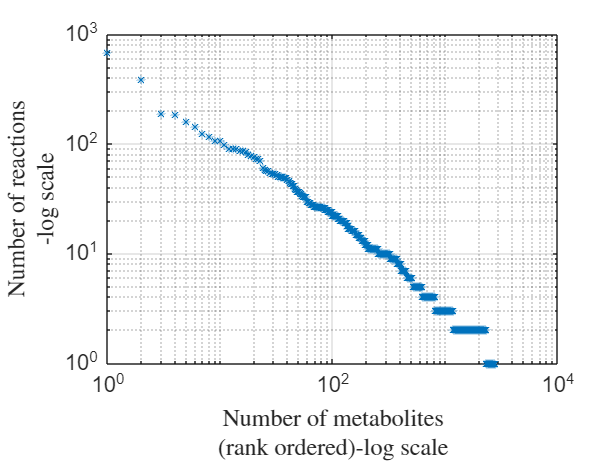

Sbin = zeros(size(model.S));
Sbin(find(model.S))=1;

for i = 1 : length(model.mets)
    metConnectivity(i,1) = sum(Sbin(i,:));
end

loglog(sort(metConnectivity,'descend'),'*');grid on;
xlabel({'Number of metabolites','(rank ordered)-log scale'},'Interpreter','latex');
ylabel({'Number of reactions','-log scale'},'Interpreter','latex');
set(gca,'FontSize',fontsize);

#### **Reaction participation **

**Description**: Reaction participation refers to the number of metabolites per reaction. To determine reaction participation for every reaction, the number of non-zero elements per column in Sbin is counted. In the Yeast cell model, there are on average 4.3 metabolites per reaction (mean(rxnParticipation)). 

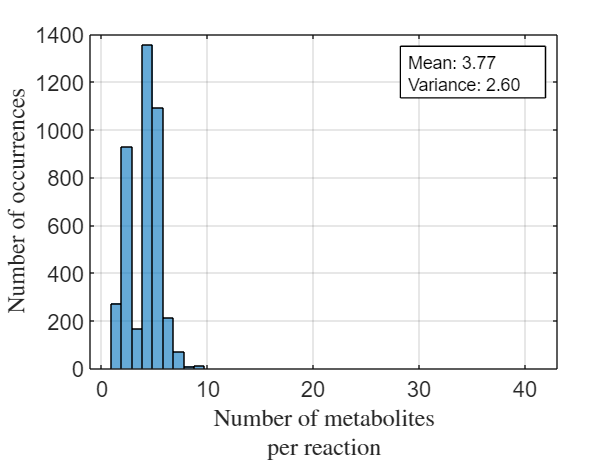

for i = 1 : length(model.rxns)
    rxnParticipation(i,1) = sum(Sbin(:,i));
end

figure;
histogram(rxnParticipation,max(unique(rxnParticipation))); grid on;
xlabel({'Number of metabolites','per reaction'},'Interpreter','latex');
ylabel('Number of occurrences','Interpreter','latex');
% Calculate statistics
m = mean(rxnParticipation);
v = var(rxnParticipation);

% Create the text string with the mean and variance
statsStr = sprintf('Mean: %.2f\nVariance: %.2f', m, v);

% Add a textbox annotation in normalized coordinates.
% [x y width height] where (x,y) is the lower-left corner in normalized units.
annotation('textbox', [0.65, 0.75, 0.25, 0.15], 'String', statsStr, ...
    'FitBoxToText', 'on', 'BackgroundColor', 'w', 'EdgeColor', 'k', 'FontSize', 12);
set(gca,'FontSize',fontsize);

#### Number of gens per reaction

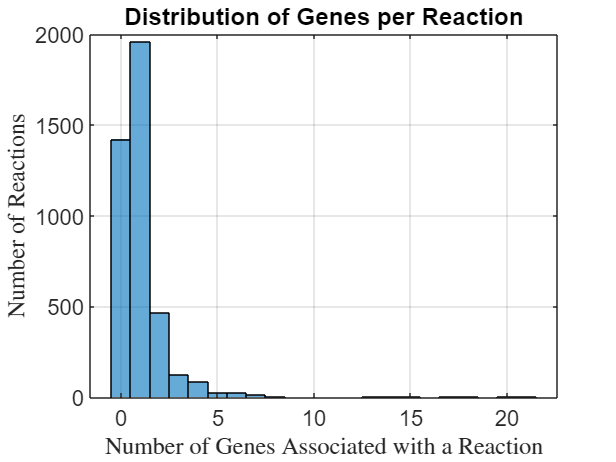


% Initialize an array to store number of genes per reaction
numGenesPerReaction = zeros(length(model.rxns), 1);

% Loop through each reaction
for i = 1:length(model.rxns)
    % Get the gene rule string
    rule = model.grRules{i};

    % Count number of unique genes in this rule (if it’s not empty)
    if ~isempty(rule)
        % Split on 'and' and 'or', then clean up parentheses and spaces
        genes = regexp(rule, '[\s()]*and[\s()]*|[\s()]*or[\s()]*', 'split');
        genes = unique(strtrim(genes));
        numGenesPerReaction(i) = length(genes);
    end
end

% Plot histogram
figure;
h=histogram(numGenesPerReaction,max(unique(numGenesPerReaction)), 'BinMethod', 'integers');
xlabel('Number of Genes Associated with a Reaction','Interpreter','latex');
ylabel('Number of Reactions','Interpreter','latex');
title('Distribution of Genes per Reaction');
grid on;
set(gca,'FontSize',fontsize);


disp(['Number of reactions catalyzed by genes: ',num2str(sum(h.BinCounts(2:end)))])

Number of reactions catalyzed by genes: 2709


#### List of genes-reaction pairs, for reactions where a single gene is needed

singleGeneRxns = [];       % To store indices of reactions with 1 gene only
singleGeneList = {};       % To store gene IDs

% Loop through each reaction
for i = 1:length(model.rxns)
    rule = model.grRules{i};

    if ~isempty(rule)
        % Split rule into individual genes using 'and', 'or', and remove whitespace/parentheses
        genes = regexp(rule, '[\s()]*and[\s()]*|[\s()]*or[\s()]*', 'split');
        genes = unique(strtrim(genes));
        
        % If only one gene is associated with the reaction
        if length(genes) == 1
            geneID = genes{1};

            % Find all reactions this gene is associated with
            geneIndex = find(strcmp(model.genes, geneID));
            associatedReactions = find(model.rxnGeneMat(:, geneIndex));

            % If this gene is only associated with one reaction
            if length(associatedReactions) == 1
                singleGeneRxns(end+1) = i; %#ok<SAGROW>
                singleGeneList{end+1} = geneID; %#ok<SAGROW>
            end
        end
    end
end

% Display results
fprintf('Total of %d Genes associated with exactly one reaction (and only in reactions that involve a single gene):\n\n',length(singleGeneList));

Total of 325 Genes associated with exactly one reaction (and only in reactions that involve a single gene):



for j = 1:length(singleGeneRxns)
    rxnIdx = singleGeneRxns(j);
    rxnID = model.rxns{rxnIdx};
    geneID = singleGeneList{j};

    % Get the subsystem (pathway)
    if iscell(model.subSystems)
        pathway = model.subSystems{rxnIdx};
    else
        pathway = model.subSystems(rxnIdx);
    end

    % Get stoichiometry of the reaction
    S_rxn = model.S(:, rxnIdx);
    substrates = model.mets(S_rxn < 0);
    products   = model.mets(S_rxn > 0);

    % Format substrates and products
    substrateStr = strjoin(strrep(substrates, '_', '\_'), ' + ');
    productStr   = strjoin(strrep(products, '_', '\_'), ' + ');
    rxnStr       = [substrateStr, ' → ', productStr];

    % Print all information
    fprintf('Gene: %-10s | Reaction: %-10s | Pathway: %-30s | Rxn: %s\n', ...
        geneID, rxnID, pathway, rxnStr);
end

Gene: YIL020C    | Reaction: r_0007     | Pathway: Histidine metabolism           | Rxn: s\_0077 → s\_0312
Gene: YOL066C    | Reaction: r_0014     | Pathway: Riboflavin metabolism          | Rxn: s\_0142 + s\_0794 + s\_0803 → s\_0313 + s\_0419
Gene: YBR153W    | Reaction: r_0015     | Pathway: Riboflavin metabolism          | Rxn: s\_0141 + s\_0794 + s\_1212 → s\_0142 + s\_1207
Gene: YHR063C    | Reaction: r_0019     | Pathway: Pantothenate and coa biosynthesis | Rxn: s\_0149 + s\_0794 + s\_1212 → s\_0030 + s\_1207
Gene: YOL064C    | Reaction: r_0032     | Pathway: Sulfur metabolism              | Rxn: s\_0390 + s\_0803 → s\_0423 + s\_1322
Gene: YDR487C    | Reaction: r_0038     | Pathway: Riboflavin metabolism          | Rxn: s\_0577 → s\_0158 + s\_0722 + s\_0794
Gene: YBR265W    | Reaction: r_0041     | Pathway: Sphingolipid metabolism        | Rxn: s\_0231 + s\_0795 + s\_1213 → s\_1208 + s\_1445
Gene: YJR025C    | Reaction: r_0058     | Pathway: Tryptophan metabolism          | Rxn:


% === Select the gene of interest ===
selectedGene = 'YDR272W';  % ← Replace with your gene ID

fprintf('Details for gene: %s\n\n', selectedGene);

Details for gene: YDR272W




% Loop over stored gene-reaction pairs
for j = 1:length(singleGeneList)
    if strcmp(singleGeneList{j}, selectedGene)
        rxnIdx = singleGeneRxns(j);
        rxnID = model.rxns{rxnIdx};
        pathway = model.subSystems{rxnIdx};

        % Get reaction stoichiometry
        S_rxn = model.S(:, rxnIdx);
        substrates = model.metNames(S_rxn < 0);
        products   = model.metNames(S_rxn > 0);

        % Format reaction string
        substrateStr = strjoin(strrep(substrates, '_', '\_'), ' + ');
        productStr   = strjoin(strrep(products, '_', '\_'), ' + ');
        rxnStr       = [substrateStr, ' → ', productStr];

        % Print everything
        fprintf('Gene:     %s\n', selectedGene);
        fprintf('Reaction: %s\n', rxnID);
        fprintf('Pathway:  %s\n', pathway);
        fprintf('Equation: %s\n\n', rxnStr);
    end
end

Gene:     YDR272W


Reaction: r_0553


Pathway:  Pyruvate metabolism


Equation: (R)-S-lactoylglutathione + H2O → (R)-lactate + glutathione + H+




%find(contains(model.genes,'leu'))

### Metabolites that are only products or only substrates

% Logical index for metabolites that are substrates (consumed)
is_substrate = any(model.S < 0, 2);

% Logical index for metabolites that are products (produced)
is_product = any(model.S > 0, 2);

% Metabolites that are only products (produced but never consumed)
only_products_idx = find(is_product & ~is_substrate);
% Get metabolite IDs of only substrates
only_product_mets = model.mets(only_products_idx);

% Display results
fprintf('Total number of metabolites that are only products: %d\n\n', numel(only_product_mets));

Total number of metabolites that are only products: 393



disp(['Percentage of metabolites that are only products ', num2str(numel(only_product_mets)/nMets*100)])

Percentage of metabolites that are only products 14.0057


disp(only_product_mets);

    {'s_0002'}
    {'s_0007'}
    {'s_0013'}
    {'s_0014'}
    {'s_0060'}
    {'s_0065'}
    {'s_0079'}
    {'s_0087'}
    {'s_0129'}
    {'s_0136'}
    {'s_0140'}
    {'s_0144'}
    {'s_0150'}
    {'s_0153'}
    {'s_0161'}
    {'s_0164'}
    {'s_0171'}
    {'s_0216'}
    {'s_0217'}
    {'s_0221'}
    {'s_0263'}
    {'s_0281'}
    {'s_0283'}
    {'s_0284'}
    {'s_0285'}
    {'s_0292'}
    {'s_0308'}
    {'s_0317'}
    {'s_0332'}
    {'s_0348'}
    {'s_0350'}
    {'s_0363'}
    {'s_0367'}
    {'s_0385'}
    {'s_0392'}
    {'s_0395'}
    {'s_0402'}
    {'s_0414'}
    {'s_0416'}
    {'s_0417'}
    {'s_0421'}
    {'s_0429'}
    {'s_0431'}
    {'s_0433'}
    {'s_0443'}
    {'s_0448'}
    {'s_0453'}
    {'s_0457'}
    {'s_0462'}
    {'s_0477'}
    {'s_0480'}
    {'s_0483'}
    {'s_0486'}
    {'s_0489'}
    {'s_0492'}
    {'s_0495'}
    {'s_0498'}
    {'s_0499'}
    {'s_0501'}
    {'s_0502'}
    {'s_0504'}
    {'s_0510'}
    {'s_0530'}
    {'s_0566'}
    {'s_0583'}
    {'s_0588'}
    {'s_06


% Metabolites that are only products (produced but never consumed)
only_substrates_idx = find(~is_product & is_substrate);
% Get metabolite IDs of only products
only_substrates_mets = model.mets(only_substrates_idx);
% Display results
fprintf('Total number of metabolites that are only substrates: %d\n\n', numel(only_substrates_mets));

Total number of metabolites that are only substrates: 486



disp(['Metabolites that are only products ', num2str(numel(only_substrates_mets)/nMets*100)])

Metabolites that are only products 17.32


disp(only_substrates_mets);

    {'s_0003'}
    {'s_0009'}
    {'s_0022'}
    {'s_0026'}
    {'s_0029'}
    {'s_0032'}
    {'s_0034'}
    {'s_0035'}
    {'s_0058'}
    {'s_0061'}
    {'s_0064'}
    {'s_0067'}
    {'s_0080'}
    {'s_0084'}
    {'s_0117'}
    {'s_0133'}
    {'s_0135'}
    {'s_0137'}
    {'s_0139'}
    {'s_0143'}
    {'s_0149'}
    {'s_0186'}
    {'s_0193'}
    {'s_0194'}
    {'s_0196'}
    {'s_0215'}
    {'s_0218'}
    {'s_0264'}
    {'s_0279'}
    {'s_0280'}
    {'s_0290'}
    {'s_0316'}
    {'s_0320'}
    {'s_0323'}
    {'s_0331'}
    {'s_0333'}
    {'s_0342'}
    {'s_0347'}
    {'s_0354'}
    {'s_0358'}
    {'s_0360'}
    {'s_0361'}
    {'s_0384'}
    {'s_0387'}
    {'s_0391'}
    {'s_0399'}
    {'s_0406'}
    {'s_0408'}
    {'s_0411'}
    {'s_0413'}
    {'s_0444'}
    {'s_0452'}
    {'s_0461'}
    {'s_0476'}
    {'s_0479'}
    {'s_0482'}
    {'s_0485'}
    {'s_0500'}
    {'s_0503'}
    {'s_0523'}
    {'s_0528'}
    {'s_0544'}
    {'s_0546'}
    {'s_0549'}
    {'s_0556'}
    {'s_0559'}
    {'s_05

### **Substrates leading to product-only metabolites**

**Description**: Find and display all linear, non-branching metabolic paths that:

- Move from one metabolite to another (substrate → product),

- Are represented as a graph of metabolites (not reactions),

- Have no bifurcations (i.e., each node has out-degree = 1),

- And ultimately end at a product-only metabolite.

#### **Part 1:** Build the Metabolite Graph

**Description**: The code loops through each reaction in your metabolic model. For each reaction:

- Finds substrates (where `S(met, rxn) < 0`) and products (`S(met, rxn) > 0`).

- Then creates edges from each substrate to each product. So if `A → B + C`, you'll create: `A → B and A → C`

**Result**: Two lists `sourceMets` and `targetMets` with parallel entries, forming directed edges from substrate to product.

% Build substrate → product edges from model
sourceMets = {};
targetMets = {};

% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %for validation only
% model.S=[ 1  -1  0  0  0; 
%           0  1  -1  0  0; 
%          -1  0   0  0  0; 
%           0  0  -1  0  1;
%           0  0 -1   -1 -1;
%           0  0  1   1  0];
% model.mets{1}='met_1';
% model.mets{2}='met_2';
% model.mets{3}='met_3';
% model.mets{4}='met_4';
% model.mets{5}='met_5';
% model.mets{6}='met_6';
% only_product_mets={'met_6'};
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for rxnIdx = 1:size(model.S,2)
    substratesIdx = find(model.S(:, rxnIdx) < 0);
    productsIdx   = find(model.S(:, rxnIdx) > 0);

    for s = 1:length(substratesIdx)
        for p = 1:length(productsIdx)
            sourceMets{end+1} = model.mets{substratesIdx(s)}; 
            targetMets{end+1} = model.mets{productsIdx(p)}; 
        end
    end
end

#### Part 2: Create and Simplify the Graph

Create a directed graph (`digraph`) where:

- Nodes = metabolite IDs

- Edges = substrate → product

G = digraph(sourceMets, targetMets);

Removing:

- Self-loops (e.g., `A → A`)

- Duplicate edges

G = simplify(G, 'omitselfloops');



#### Part 3: Define Product-Only Endpoints

**Description**:

- It filters the `only_product_mets` list (your input) to include only those metabolites that are actually in the graph.

- These are the target endpoints of the paths you're looking for.

% Convert product-only metabolites to graph node names
product_only_nodes = intersect(G.Nodes.Name, only_product_mets);

#### Part 4: Identify Starting Points for Paths

**Description**:

- Identify nodes with exactly one outward connection — i.e., they can be the beginning of a linear path.

- We don't care about in-degree (a node can be made from many reactions), but we do care that it only contributes to one next step.

% Start condition: nodes with out-degree = 1 (can have any in-degree)
starts = find(outdegree(G) == 1);

#### Part 5: Trace Paths

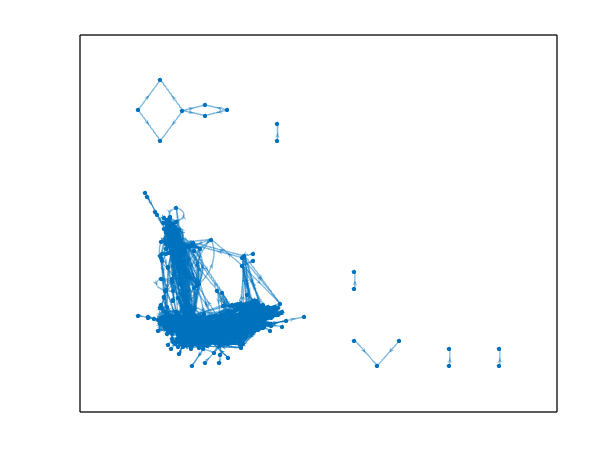

% Initialize list of linear paths
linear_paths = {};
% Loop through each start node
for i = 1:length(starts)
    path = G.Nodes.Name(starts(i));%temporal variable to save the path from start nodes
    current = starts(i);%flag to avoid visiting the same node multiple times

    visited = false(height(G.Nodes), 1); % to avoid cycles

    % Trace forward until bifurcation or endpoint
    % While-loop: keeps walking through the path.
    % Stops if: no next node (dead end).
    while true
        visited(current) = true;%flag set to one as this node is currently visited
        successors_list = successors(G, current);%look for the child node from the current one

        % Stop if path ends
        if isempty(successors_list)
            break;
        end

        %find the name of the child node
        next_name = G.Nodes.Name{successors_list(1)};
        %find the index of the child node
        next = find(strcmp(G.Nodes.Name, next_name));

        % Stop if bifurcation or already visited (avoid cycles)
        if outdegree(G, next) > 1 || visited(next)
            break;
        end

        % If there is any biffurcation add next node
        path{end+1} = next_name;
        %place the current node with the next visiting one
        current = next;
    end

    % The above while-loop path is recorded only if path ends at a product-only metabolite
    if ismember(path{end}, product_only_nodes)
        linear_paths{end+1} = path;
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%for validation only
figure;
plot(G)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Display paths
if isempty(linear_paths)
    fprintf('There is any single substrate to a metabolite-product only');
else
    for i = 1:length(linear_paths)
        fprintf('Linear (non-branching) pathways that lead to product-only metabolites:\n\n');
        fprintf('Path %d:\n', i);
        disp(strjoin(linear_paths{i}, ' → '));
    end
end

Linear (non-branching) pathways that lead to product-only metabolites:



Path 1:


s_0853 → s_0854


Linear (non-branching) pathways that lead to product-only metabolites:



Path 2:


s_1321 → s_4194


Linear (non-branching) pathways that lead to product-only metabolites:



Path 3:


s_1522 → s_0566


Linear (non-branching) pathways that lead to product-only metabolites:



Path 4:


s_1541 → s_1542


Linear (non-branching) pathways that lead to product-only metabolites:



Path 5:


s_0774 → s_0566


Linear (non-branching) pathways that lead to product-only metabolites:



Path 6:


s_1323 → s_2966


Linear (non-branching) pathways that lead to product-only metabolites:



Path 7:


s_0720 → s_0719


Linear (non-branching) pathways that lead to product-only metabolites:



Path 8:


s_0080 → s_0079


Linear (non-branching) pathways that lead to product-only metabolites:



Path 9:


s_0892 → s_3724


Linear (non-branching) pathways that lead to product-only metabolites:



Path 10:


s_0859 → s_3723


Linear (non-branching) pathways that lead to product-only metabolites:



Path 11:


s_1114 → s_3725


Linear (non-branching) pathways that lead to product-only metabolites:



Path 12:


s_0775 → s_0777


Linear (non-branching) pathways that lead to product-only metabolites:



Path 13:


s_0137 → s_0136


Linear (non-branching) pathways that lead to product-only metabolites:



Path 14:


s_0776 → s_0775 → s_0777


Linear (non-branching) pathways that lead to product-only metabolites:



Path 15:


s_1044 → s_1043


Linear (non-branching) pathways that lead to product-only metabolites:



Path 16:


s_1564 → s_1563


Linear (non-branching) pathways that lead to product-only metabolites:



Path 17:


s_2822 → s_2828 → s_2882


Linear (non-branching) pathways that lead to product-only metabolites:



Path 18:


s_2828 → s_2882


Linear (non-branching) pathways that lead to product-only metabolites:



Path 19:


s_2824 → s_2829 → s_2883


Linear (non-branching) pathways that lead to product-only metabolites:



Path 20:


s_2829 → s_2883


Linear (non-branching) pathways that lead to product-only metabolites:



Path 21:


s_3495 → s_0079


Linear (non-branching) pathways that lead to product-only metabolites:



Path 22:


s_3721 → s_3722


Linear (non-branching) pathways that lead to product-only metabolites:



Path 23:


s_3726 → s_3727


Linear (non-branching) pathways that lead to product-only metabolites:



Path 24:


s_3728 → s_3729


Linear (non-branching) pathways that lead to product-only metabolites:



Path 25:


s_3730 → s_3731


Linear (non-branching) pathways that lead to product-only metabolites:



Path 26:


s_3732 → s_3733


Linear (non-branching) pathways that lead to product-only metabolites:



Path 27:


s_3734 → s_3735


Linear (non-branching) pathways that lead to product-only metabolites:



Path 28:


s_3736 → s_3737


Linear (non-branching) pathways that lead to product-only metabolites:



Path 29:


s_3738 → s_3739


Linear (non-branching) pathways that lead to product-only metabolites:



Path 30:


s_3787 → s_3788


Linear (non-branching) pathways that lead to product-only metabolites:



Path 31:


s_4026 → s_4027


Linear (non-branching) pathways that lead to product-only metabolites:



Path 32:


s_3952 → s_3950


Linear (non-branching) pathways that lead to product-only metabolites:



Path 33:


s_4006 → s_4008


Linear (non-branching) pathways that lead to product-only metabolites:



Path 34:


s_4007 → s_4008


Linear (non-branching) pathways that lead to product-only metabolites:



Path 35:


s_4114 → s_4112


Linear (non-branching) pathways that lead to product-only metabolites:



Path 36:


s_4176 → s_3837


Linear (non-branching) pathways that lead to product-only metabolites:



Path 37:


s_4268 → s_4267


#### Looking for substrates per reaction


% Initialize a cell array to hold reaction IDs and their substrate lists
rxn_substrates = cell(numel(model.rxns), 2);

% Loop over each reaction in the model
for j = 1:numel(model.rxns)
    % Get the reaction ID (or name)
    rxnID = model.rxns{j};
    
    % Find indices of metabolites that have negative stoichiometric coefficient in this reaction
    subs_idx = find(model.S(:, j) < 0);
    
    % Get the metabolite IDs for these substrates
    subs_list = model.mets(subs_idx);
    
    % Store the reaction ID and its substrates in the cell array
    rxn_substrates{j, 1} = rxnID;
    rxn_substrates{j, 2} = subs_list;
    
    % (Optional) Display the reaction and its substrates
    fprintf('%s: %s\n', rxnID, strjoin(subs_list, ', '));
end

r_0001: s_0025, s_0709
r_0002: s_0027, s_0709
r_0003: s_0035, s_1198
r_0004: s_0063, s_0709
r_0005: s_1543
r_0006: s_1543
r_0007: s_0077
r_0012: s_0119, s_0807, s_1200
r_0013: s_0311, s_0803
r_0014: s_0142, s_0794, s_0803
r_0015: s_0141, s_0794, s_1212
r_0016: s_0179, s_0799, s_1401
r_0017: s_0148, s_0437
r_0018: s_0176, s_0991
r_0019: s_0149, s_0794, s_1212
r_0020: s_0552, s_0807, s_1361
r_0021: s_0155, s_1419
r_0022: s_0157, s_1278
r_0023: s_0165, s_0803
r_0024: s_0232, s_0373, s_0803
r_0025: s_0233, s_0376, s_0807
r_0026: s_0294, s_0991
r_0027: s_0834
r_0028: s_0807, s_1273, s_1382
r_0029: s_0010, s_0794
r_0030: s_0011, s_0799
r_0032: s_0390, s_0803
r_0033: s_0192, s_0803
r_0034: s_0194, s_0803
r_0035: s_0196, s_0803
r_0036: s_0195, s_0803
r_0037: s_0193, s_0803
r_0038: s_0577
r_0039: s_0210
r_0040: s_0349
r_0041: s_0231, s_0795, s_1213
r_0042: s_0551, s_0803, s_1360
r_0043: s_0215, s_1275
r_0044: s_0214, s_0799
r_0045: s_0222, s_0803
r_0057: s_0054, s_1202
r_0058: s_0224, s_1275
r_

### Looking for extracellular substrates per reaction

% Initialize cell array to hold transport reactions with extracellular substrates
transportSubstrates = {};

% Loop over reactions
for j = 1:numel(model.rxns)
    % Get indices of substrates (negative stoichiometry)
    subs_idx = find(model.S(:, j) < 0);
    subs_mets = model.mets(subs_idx);
    
    % Check if any substrate is extracellular (suffix '_e')
    isExtracellular = endsWith(subs_mets, '_e');
    
    if any(isExtracellular)
        % Store reaction ID and extracellular substrates
        transportSubstrates(end+1).reaction = model.rxns{j}; %#ok<SAGROW>
        transportSubstrates(end).substrates = subs_mets(isExtracellular);
        
        % Display reaction and extracellular substrate metabolites
        fprintf('Reaction %s imports: %s\n', model.rxns{j}, strjoin(subs_mets(isExtracellular), ', '));
    end
end


### External substrates where the products is an specific metabolite

% Identify metabolite index for uracil (typically 'uracil_c' or similar)
uracil_met_idx = find(contains(model.mets, 'ura_c'));

% Find reactions producing uracil (positive stoichiometric coefficient)
met_rxns_idx = find(model.S(uracil_met_idx, :) > 0);
met_rxns = model.rxns(met_rxns_idx);

% Check each reaction for extracellular imported metabolites
for i = 1:length(met_rxns_idx)
    rxn_idx = met_rxns_idx(i);
    substrates_idx = find(model.S(:, rxn_idx) < 0);
    substrates = model.mets(substrates_idx);
    
    % Identify extracellular metabolites
    extracellular_substrates = substrates(endsWith(substrates, '_e'));
    
    % Display reaction details
    fprintf('\nReaction producing uracil: %s\n', model.rxns{rxn_idx});
    disp(printRxnFormula(model, model.rxns{rxn_idx}));
    
    if ~isempty(extracellular_substrates)
        fprintf('Extracellular substrates imported: %s\n', strjoin(extracellular_substrates, ', '));
    else
        fprintf('No extracellular substrates imported.\n');
    end
end


### Metabolites that are only substrates of reactions

% Logical index of metabolites that are substrates (consumed)
is_substrate = any(model.S < 0, 2);

% Logical index of metabolites that are products (produced)
is_product = any(model.S > 0, 2);

% Metabolites that are only substrates (consumed but never produced)
only_substrates_idx = find(is_substrate & ~is_product);

% Get metabolite IDs
only_substrates = model.mets(only_substrates_idx);

% Display result
disp(['Percentage of metabolites that are only substrates: ', num2str(numel(only_substrates)/nMets*100)]);

Percentage of metabolites that are only substrates: 17.32


fprintf('Metabolites that are only substrates:\n');

Metabolites that are only substrates:


disp(only_substrates);

    {'s_0003'}
    {'s_0009'}
    {'s_0022'}
    {'s_0026'}
    {'s_0029'}
    {'s_0032'}
    {'s_0034'}
    {'s_0035'}
    {'s_0058'}
    {'s_0061'}
    {'s_0064'}
    {'s_0067'}
    {'s_0080'}
    {'s_0084'}
    {'s_0117'}
    {'s_0133'}
    {'s_0135'}
    {'s_0137'}
    {'s_0139'}
    {'s_0143'}
    {'s_0149'}
    {'s_0186'}
    {'s_0193'}
    {'s_0194'}
    {'s_0196'}
    {'s_0215'}
    {'s_0218'}
    {'s_0264'}
    {'s_0279'}
    {'s_0280'}
    {'s_0290'}
    {'s_0316'}
    {'s_0320'}
    {'s_0323'}
    {'s_0331'}
    {'s_0333'}
    {'s_0342'}
    {'s_0347'}
    {'s_0354'}
    {'s_0358'}
    {'s_0360'}
    {'s_0361'}
    {'s_0384'}
    {'s_0387'}
    {'s_0391'}
    {'s_0399'}
    {'s_0406'}
    {'s_0408'}
    {'s_0411'}
    {'s_0413'}
    {'s_0444'}
    {'s_0452'}
    {'s_0461'}
    {'s_0476'}
    {'s_0479'}
    {'s_0482'}
    {'s_0485'}
    {'s_0500'}
    {'s_0503'}
    {'s_0523'}
    {'s_0528'}
    {'s_0544'}
    {'s_0546'}
    {'s_0549'}
    {'s_0556'}
    {'s_0559'}
    {'s_05

**Description**: Find and display all linear, non-branching metabolic paths that:

- Move from one metabolite to another (substrate → product),

- Are represented as a graph of metabolites (not reactions),

- Have no bifurcations (i.e., each node has out-degree = 1),

- And ultimately end at a product-only metabolite.

**Part 1:** Build the Metabolite Graph

Description: The code loops through each reaction in your metabolic model. For each reaction:

- Finds substrates (where `S(met, rxn) < 0`) and products (`S(met, rxn) > 0`).

- Then creates edges from each substrate to each product.

- So if `A → B + C`, you'll create:

- `A → B`

- `A → C`

Result: two lists `sourceMets` and `targetMets` with parallel entries, forming directed edges from substrate to product.

% Build substrate → product edges from model
sourceMets = {};
targetMets = {};

for rxnIdx = 1:length(model.rxns)
    substratesIdx = find(model.S(:, rxnIdx) < 0);
    productsIdx   = find(model.S(:, rxnIdx) > 0);

    for s = 1:length(substratesIdx)
        for p = 1:length(productsIdx)
            sourceMets{end+1} = model.mets{substratesIdx(s)}; %#ok<SAGROW>
            targetMets{end+1} = model.mets{productsIdx(p)};   %#ok<SAGROW>
        end
    end
end

% Create digraph
G = digraph(sourceMets, targetMets);
G = simplify(G, 'omitselfloops');
figure;
plot(G)


% Convert product-only metabolites to graph node names
product_only_nodes = intersect(G.Nodes.Name, only_product_mets);

% Initialize list of linear paths
linear_paths = {};

% ?Modified start condition: nodes with out-degree = 1 (can have any in-degree)
starts = find(outdegree(G) == 1);

for i = 1:length(starts)
    path = G.Nodes.Name(starts(i));
    current = starts(i);

    visited = false(height(G.Nodes), 1); % to avoid cycles

    % Trace forward until bifurcation or endpoint
    while true
        visited(current) = true;
        successors_list = successors(G, current);

        % Stop if path ends
        if isempty(successors_list)
            break;
        end

        next_name = successors_list(1);
        next = find(strcmp(G.Nodes.Name, next_name));

        if isempty(next)
            break;
        end
        % Stop if bifurcation or already visited (avoid cycles)
        if outdegree(G, next) ~= 1 || visited(next)
            break;
        end

        % Add next node
        path{end+1} = next_name; %#ok<SAGROW>
        current = next;
    end

    % Keep only if path ends at a product-only metabolite
    if ismember(path{end}, product_only_nodes)
        linear_paths{end+1} = path; %#ok<SAGROW>
    end
end

% Display paths
fprintf('Linear (non-branching) pathways that lead to product-only metabolites:\n\n');

Linear (non-branching) pathways that lead to product-only metabolites:



for i = 1:length(linear_paths)
    fprintf('Path %d:\n', i);
    disp(strjoin(linear_paths{i}, ' → '));
end


### Metabolites substrates-only that are part of a metabolic pathway of a single metabolic-product

% Convert only_product_mets (if they are names) to indices
only_product_idx = find(ismember(model.mets, only_product_mets));

% Initialize results: {substrate, product, reaction}
unique_substrate_to_single_product = {};

% Loop through all substrate-only metabolites
for i = 1:length(only_substrates_idx)
    sub_idx = only_substrates_idx(i);
    sub_id = model.mets{sub_idx};
    
    % Find reactions where this metabolite is consumed
    rxns_with_sub = find(model.S(sub_idx, :) < 0);

    for r = rxns_with_sub
        % Find all products of this reaction
        prod_idx = find(model.S(:, r) > 0);
        
        % If only one product and it's in the only-products list
        if numel(prod_idx) == 1 && ismember(prod_idx, only_product_idx)
            product_id = model.mets{prod_idx};
            rxn_id = model.rxns{r};
            
            % Store substrate, product, and reaction
            unique_substrate_to_single_product{end+1,1} = sub_id;      
            unique_substrate_to_single_product{end,2} = product_id;
            unique_substrate_to_single_product{end,3} = rxn_id;
        end
    end
end

% Display results
fprintf('Substrates that produce a single "only-product" via one reaction:\n\n');

Substrates that produce a single "only-product" via one reaction:



for k = 1:size(unique_substrate_to_single_product, 1)
    fprintf('Substrate: %-20s → Product: %-20s via Reaction: ', ...
        unique_substrate_to_single_product{k,1}, ...
        unique_substrate_to_single_product{k,2});
    printRxnFormula(model, unique_substrate_to_single_product{k,3});
    fprintf('\n');

end

Substrate: s_0080               → Product: s_0079               via Reaction: 

r_1169	s_0080 	<=>	s_0079 


Substrate: s_0137               → Product: s_0136               via Reaction: 

r_1733	s_0137 	->	s_0136 


Substrate: s_0149               → Product: s_0150               via Reaction: 

r_1568	s_0149 	<=>	s_0150 


Substrate: s_0215               → Product: s_0216               via Reaction: 

r_1601	s_0215 	<=>	s_0216 


Substrate: s_0218               → Product: s_0221               via Reaction: 

r_1840	s_0218 	<=>	s_0221 


Substrate: s_0347               → Product: s_0348               via Reaction: 

r_1745	s_0347 	<=>	s_0348 


Substrate: s_0500               → Product: s_0499               via Reaction: 

r_1678	s_0500 	<=>	s_0499 


Substrate: s_0503               → Product: s_0502               via Reaction: 

r_1681	s_0503 	<=>	s_0502 


Substrate: s_0528               → Product: s_3219               via Reaction: 

r_3959	s_0528 	<=>	s_3219 


Substrate: s_0720               → Product: s_0719               via Reaction: 

r_1164	s_0720 	<=>	s_0719 


Substrate: s_1044               → Product: s_1043               via Reaction: 

r_1910	s_1044 	<=>	s_1043 


Substrate: s_1073               → Product: s_2843               via Reaction: 

r_3575	s_1073 	<=>	s_2843 


Substrate: s_1079               → Product: s_0013               via Reaction: 

r_0703	s_0803 + s_1079 	<=>	s_0013 


Substrate: s_1079               → Product: s_0608               via Reaction: 

r_0705	s_0803 + s_1079 	<=>	s_0608 


Substrate: s_1079               → Product: s_1081               via Reaction: 

r_0707	s_0803 + s_1079 	<=>	s_1081 


Substrate: s_1080               → Product: s_0014               via Reaction: 

r_0704	s_0808 + s_1080 	<=>	s_0014 


Substrate: s_1080               → Product: s_0609               via Reaction: 

r_0706	s_0808 + s_1080 	<=>	s_0609 


Substrate: s_1080               → Product: s_1082               via Reaction: 

r_0708	s_0808 + s_1080 	<=>	s_1082 


Substrate: s_1107               → Product: s_1108               via Reaction: 

r_1932	s_1107 	<=>	s_1108 


Substrate: s_1176               → Product: s_2845               via Reaction: 

r_3576	s_1176 	<=>	s_2845 


Substrate: s_1564               → Product: s_1563               via Reaction: 

r_2103	s_1564 	->	s_1563 


Substrate: s_3764               → Product: s_4025               via Reaction: 

r_4339	s_3764 	<=>	s_4025 


Substrate: s_3787               → Product: s_3788               via Reaction: 

r_4174	s_3787 	<=>	s_3788 


Substrate: s_3998               → Product: s_4193               via Reaction: 

r_4586	s_3998 + s_4192 	->	2 s_4193 


Substrate: s_4006               → Product: s_4008               via Reaction: 

r_4325	s_4006 + s_4007 	->	s_4008 


Substrate: s_4007               → Product: s_4008               via Reaction: 

r_4325	s_4006 + s_4007 	->	s_4008 


Substrate: s_4026               → Product: s_4027               via Reaction: 

r_4195	s_4026 	<=>	s_4027 


Substrate: s_4114               → Product: s_4112               via Reaction: 

r_4383	s_4114 	<=>	s_4112 


Substrate: s_4176               → Product: s_3837               via Reaction: 

r_4478	s_4176 	<=>	s_3837 


Substrate: s_4192               → Product: s_4193               via Reaction: 

r_4586	s_3998 + s_4192 	->	2 s_4193 


Substrate: s_4251               → Product: s_4250               via Reaction: 

r_4686	s_4251 	<=>	s_4250 


Substrate: s_4268               → Product: s_4267               via Reaction: 

r_4705	s_4268 	->	s_4267 


### Substrates that contribute to a single product-only metabolite

% Convert product-only metabolite names to indices
only_product_idx = find(ismember(model.mets, only_product_mets));

% Initialize mapping: substrate → list of product-only targets
substrate_product_map = containers.Map();

% Loop through each product-only metabolite
for i = 1:length(only_product_idx)
    %copying the metabolite-product index
    prod_idx = only_product_idx(i);
    %fetching the metabolite-product name
    prod_id = model.mets{prod_idx};

    % Find reactions that produce this product
    producing_rxns = find(model.S(prod_idx, :) > 0);

    % Loops through each reaction that produces the current product
    for r = 1:length(producing_rxns)
        rxn = producing_rxns(r);

        % Find substrates in the reaction
        subs_idx = find(model.S(:, rxn) < 0);

        % Loop through each substrate of that particular reaction
        for s = 1:length(subs_idx)
            sub_id = model.mets{subs_idx(s)};

            % Add this product to the substrate's impact list
            if isKey(substrate_product_map, sub_id)
                existing = substrate_product_map(sub_id);
                substrate_product_map(sub_id) = unique([existing; {prod_id}]);
            else
                substrate_product_map(sub_id) = {prod_id};
            end
        end
    end
end

% Filter: substrates that only impact ONE unique product
single_product_substrates = {};
for k = keys(substrate_product_map)
    sub_id = k{1};
    targets = substrate_product_map(sub_id);
    if numel(targets) == 1
        single_product_substrates{end+1,1} = sub_id;              %#ok<SAGROW>
        single_product_substrates{end,2} = targets{1};            % the single product
    end
end

% Display results
fprintf('Substrates that impact only ONE product-only metabolite:\n\n');

Substrates that impact only ONE product-only metabolite:



for i = 1:size(single_product_substrates,1)
    fprintf('Substrate: %-20s → Product: %s\n', ...
        single_product_substrates{i,1}, ...
        single_product_substrates{i,2});
end

Substrate: s_0001               → Product: s_0002
Substrate: s_0006               → Product: s_0348
Substrate: s_0008               → Product: s_0060
Substrate: s_0009               → Product: s_0217
Substrate: s_0011               → Product: s_0292
Substrate: s_0042               → Product: s_1206
Substrate: s_0045               → Product: s_1206
Substrate: s_0048               → Product: s_1206
Substrate: s_0051               → Product: s_1206
Substrate: s_0054               → Product: s_1206
Substrate: s_0056               → Product: s_0060
Substrate: s_0063               → Product: s_0065
Substrate: s_0069               → Product: s_1206
Substrate: s_0075               → Product: s_0140
Substrate: s_0080               → Product: s_0079
Substrate: s_0121               → Product: s_0713
Substrate: s_0132               → Product: s_0136
Substrate: s_0134               → Product: s_4305
Substrate: s_0137               → Product: s_0136
Substrate: s_0143               → Product: s_0144


% Loop over all product-only metabolites
all_subs = keys(substrate_product_map);

% Build a reverse map: product → {substrates that lead to it}
product_to_substrates = containers.Map();

for i = 1:length(all_subs)
    substrate = all_subs{i};
    products = substrate_product_map(substrate);

    % For each product this substrate affects
    for j = 1:length(products)
        product = products{j};

        if isKey(product_to_substrates, product)
            existing = product_to_substrates(product);
            product_to_substrates(product) = unique([existing; {substrate}]);
        else
            product_to_substrates(product) = {substrate};
        end
    end
end

% Plot one graph per product-only metabolite
product_list = keys(product_to_substrates);

% for p = 1:length(product_list)
for p = 1:1
    product = product_list{p};
    substrates = product_to_substrates(product);

    % Skip if only one substrate (not a "path")
    if length(substrates) < 2
        continue
    end

    % Create edges: each substrate → this product
    source_nodes = substrates;
    target_nodes = repmat({product}, size(substrates));

    % Create and plot the graph
    G = digraph(source_nodes, target_nodes);
    
    figure;
    plot(G, ...
        'Layout', 'layered', ...
        'NodeLabel', G.Nodes.Name, ...
        'ArrowSize', 10, ...
        'MarkerSize', 6);
    
    title(['Pathway to Product: ', strrep(product, '_', '\_')]);
end



### External substrates that are unique to produce an specific metabolite

% Identify metabolite index for uracil (typically 'uracil_c' or similar)
met_name='his_c';
met_idx = find(contains(model.mets, met_name));

if(isempty(met_idx))%validating
    fprintf('There is no metabolite that includes %s:\n',met_name);
else
    for i=1:length(met_idx)
        fprintf('Found metabolite %s of index %d\n',model.mets{met_idx(i)},met_idx(i));
    end

    % Find reactions producing uracil (positive coefficient)
    met_rxns_idx = find(model.S(met_idx, :) > 0);
    met_rxns = model.rxns(met_idx);

    if(isempty(met_rxns_idx))%validtaing
        fprintf('Metabolite %s is not a product of any reaction\n',model.mets{met_idx(i)});
    else
        % Loop through each reaction producing the metabolite
        for i = 1:length(met_rxns_idx)
            fprintf('Analyzing reaction %s:\n',model.rxnNames{met_rxns_idx(i)});
            rxn_idx = met_rxns_idx(i);

            % Substrates in this reaction (negative coefficients)
            subs_idx = find(model.S(:, rxn_idx) < 0);
            substrates = model.mets(subs_idx);

            unique_substrates = {};

            % Check each substrate to see if it participates in other reactions
            for j = 1:length(subs_idx)
                met_idx = subs_idx(j);

                % Count the number of reactions involving this metabolite
                reactions_involved = find(model.S(met_idx, :) ~= 0);

                % If metabolite participates only in this reaction
                if numel(reactions_involved) == 1
                    unique_substrates{end+1} = model.mets{met_idx}; %#ok<SAGROW>
                end
            end

            % Display the reaction and unique substrates
            fprintf('\nReaction %s producing %s:\n', model.rxns{rxn_idx},met_name);
            disp(printRxnFormula(model, model.rxns{rxn_idx}));

            if ~isempty(unique_substrates)
                fprintf('Unique substrates (not in other reactions): %s\n', strjoin(unique_substrates, ', '));
            else
                fprintf('No unique substrates; all substrates participate in other reactions.\n');
            end
        end


    end

end

There is no metabolite that includes his_c:


### Substrates that are unique to reactions

% Load the model
model = readCbModel('iMM904.mat');

Each model.subSystems{x} is a character array, and this format is retained.



% Initialize storage for unique substrates
unique_substrates = {};

% Loop through each metabolite to check if it's a unique substrate
for met_idx = 1:length(model.mets)
    
    % Find reactions where this metabolite is a substrate (negative coefficient)
    rxns_as_substrate = find(model.S(met_idx,:) < 0);
    
    % Skip metabolites not used as substrates at all
    if isempty(rxns_as_substrate)
        continue
    end
    
    % Find all metabolites produced (positive coefficients) by these reactions
    produced_metabolites = [];
    for rxn = rxns_as_substrate
        produced_metabolites = [produced_metabolites; find(model.S(:,rxn) > 0)];
    end
    produced_metabolites = unique(produced_metabolites);
    
    % If exactly one metabolite is produced by these reactions,
    % the substrate is specific for producing that metabolite
    if numel(produced_metabolites) == 1
        unique_substrates{end+1,1} = model.mets{met_idx}; %#ok<SAGROW>
        unique_substrates{end,2} = model.mets{produced_metabolites};
    end
end

% Display results
fprintf('Substrates uniquely associated with producing a single metabolite:\n\n');

Substrates uniquely associated with producing a single metabolite:



for k = 1:size(unique_substrates,1)
    fprintf('Substrate: %s \t exclusively produces: %s\n', unique_substrates{k,1}, unique_substrates{k,2});
end

Substrate: 2hpmmbq_m 	 exclusively produces: 2hpmhmbq_m
Substrate: 2ippm_c 	 exclusively produces: 3c3hmp_c
Substrate: 2mbac_c 	 exclusively produces: 2mbac_e
Substrate: 2mcit_m 	 exclusively produces: micit_m
Substrate: 2obut_c 	 exclusively produces: 2obut_m
Substrate: 2oxoadp_m 	 exclusively produces: 2oxoadp_c
Substrate: 2phetoh_e 	 exclusively produces: 2phetoh_c
Substrate: 2phetoh_m 	 exclusively produces: 2phetoh_c
Substrate: 13BDglcn_e 	 exclusively produces: glc__D_e
Substrate: 4hbz_c 	 exclusively produces: 4hbz_m
Substrate: 4hpro_LT_c 	 exclusively produces: 4hpro_LT_m
Substrate: 3dh5hpb_c 	 exclusively produces: 3dh5hpb_m
Substrate: 4mlacac_c 	 exclusively produces: 4fumacac_c
Substrate: 23camp_c 	 exclusively produces: amp2p_c
Substrate: 5mdr1p_c 	 exclusively produces: 5mdru1p_c
Substrate: 3mop_e 	 exclusively produces: 3mop_c
Substrate: Nbfortyr_c 	 exclusively produces: Nbfortyr_e
Substrate: Ssq23epx_c 	 exclusively produces: lanost_c
Substrate: 4abutn_c 	 exclusively p

### Substrates that are unique to produce any metabolite

% Initialize storage for unique substrates
unique_substrates = {};

% Loop through each metabolite to check if it's a unique substrate
for met_idx = 1:length(model.mets)
    
    % Find reactions where this metabolite is a substrate (negative coefficient)
    rxns_as_substrate = find(model.S(met_idx,:) < 0);
    
    % Skip metabolites not used as substrates at all
    if isempty(rxns_as_substrate)
        continue
    end
    
    % Find all metabolites produced (positive coefficients) by these reactions
    produced_metabolites = [];
    for rxn = rxns_as_substrate
        produced_metabolites = [produced_metabolites; find(model.S(:,rxn) > 0)];
    end
    produced_metabolites = unique(produced_metabolites);
    
    % If exactly one metabolite is produced by these reactions,
    % the substrate is specific for producing that metabolite
    if numel(produced_metabolites) == 1
        unique_substrates{end+1,1} = model.mets{met_idx}; %#ok<SAGROW>
        unique_substrates{end,2} = model.mets{produced_metabolites};
    end
end

% Display results
disp(['Percentage of metabolites that are unique substrates and substrates only: ', num2str(size(unique_substrates,1)/nMets*100)]);

Percentage of metabolites that are unique substrates and substrates only: 3.5282


fprintf('Substrates uniquely associated with producing a single metabolite:\n\n');

Substrates uniquely associated with producing a single metabolite:



for k = 1:size(unique_substrates,1)
    fprintf('Substrate: %s \t exclusively produces: %s\n', unique_substrates{k,1}, unique_substrates{k,2});
end

Substrate: 2hpmmbq_m 	 exclusively produces: 2hpmhmbq_m
Substrate: 2ippm_c 	 exclusively produces: 3c3hmp_c
Substrate: 2mbac_c 	 exclusively produces: 2mbac_e
Substrate: 2mcit_m 	 exclusively produces: micit_m
Substrate: 2obut_c 	 exclusively produces: 2obut_m
Substrate: 2oxoadp_m 	 exclusively produces: 2oxoadp_c
Substrate: 2phetoh_e 	 exclusively produces: 2phetoh_c
Substrate: 2phetoh_m 	 exclusively produces: 2phetoh_c
Substrate: 13BDglcn_e 	 exclusively produces: glc__D_e
Substrate: 4hbz_c 	 exclusively produces: 4hbz_m
Substrate: 4hpro_LT_c 	 exclusively produces: 4hpro_LT_m
Substrate: 3dh5hpb_c 	 exclusively produces: 3dh5hpb_m
Substrate: 4mlacac_c 	 exclusively produces: 4fumacac_c
Substrate: 23camp_c 	 exclusively produces: amp2p_c
Substrate: 5mdr1p_c 	 exclusively produces: 5mdru1p_c
Substrate: 3mop_e 	 exclusively produces: 3mop_c
Substrate: Nbfortyr_c 	 exclusively produces: Nbfortyr_e
Substrate: Ssq23epx_c 	 exclusively produces: lanost_c
Substrate: 4abutn_c 	 exclusively p

### Unique substrates that lead to the production of extracellular metabolites

% Assume 'model' and 'unique_substrates' are already defined

fprintf('Unique substrates that produce extracellular metabolites:\n\n');

Unique substrates that produce extracellular metabolites:




% Loop through the unique substrate-product pairs
for k = 1:size(unique_substrates, 1)
    substrate = unique_substrates{k, 1};
    product   = unique_substrates{k, 2};

    % Check if the product is extracellular
    if endsWith(product, '_e')
        % Get indices in model
        substrate_idx = find(strcmp(model.mets, substrate));
        product_idx   = find(strcmp(model.mets, product));
        
        % Find reactions that consume the substrate and produce the product
        rxn_idx = find((model.S(substrate_idx, :) < 0) & (model.S(product_idx, :) > 0));

        % Print result(s)
        for r = 1:length(rxn_idx)
            rxnID = model.rxns{rxn_idx(r)};
            fprintf('Substrate: %s\n', substrate);
            fprintf('Product  : %s\n', product);
            reaction=printRxnFormula(model, rxnID);
            fprintf('Reaction : %s\n\n', reaction{1});
        end
    end
end

Substrate: 2mbac_c


Product  : 2mbac_e


2MBACt	2mbac_c 	->	2mbac_e 


Reaction : 2mbac_c  -> 2mbac_e 



Substrate: 13BDglcn_e


Product  : glc__D_e


13BGHe	13BDglcn_e + h2o_e 	->	glc__D_e 


Reaction : 13BDglcn_e + h2o_e  -> glc__D_e 



Substrate: Nbfortyr_c


Product  : Nbfortyr_e


NFORTYRt	Nbfortyr_c 	->	Nbfortyr_e 


Reaction : Nbfortyr_c  -> Nbfortyr_e 



Substrate: pectin_e


Product  : galur_e


EPGALURSe	h2o_e + pectin_e 	->	galur_e 


Reaction : h2o_e + pectin_e  -> galur_e 



Substrate: pheac_c


Product  : pheac_e


PHEACt	pheac_c 	->	pheac_e 


Reaction : pheac_c  -> pheac_e 



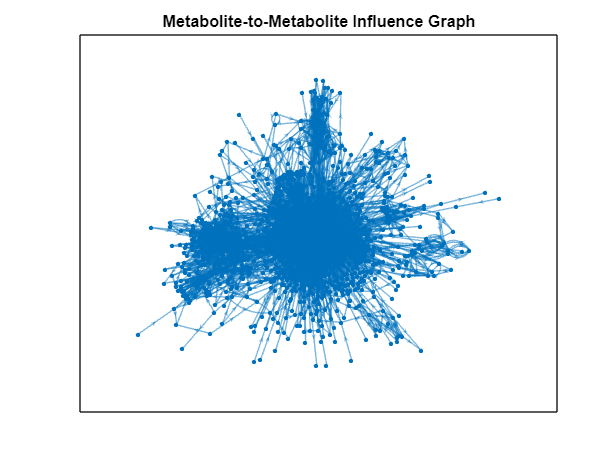

% Initialize source-target lists for graph edges
sourceMets = {};
targetMets = {};

% Loop over reactions
for rxnIdx = 1:length(model.rxns)
    % Find substrate and product indices for this reaction
    substratesIdx = find(model.S(:, rxnIdx) < 0);
    productsIdx   = find(model.S(:, rxnIdx) > 0);
    
    % Build all pairwise substrate → product edges
    for s = 1:length(substratesIdx)
        for p = 1:length(productsIdx)
            sourceMets{end+1} = model.mets{substratesIdx(s)}; %#ok<SAGROW>
            targetMets{end+1} = model.mets{productsIdx(p)};   %#ok<SAGROW>
        end
    end
end

% Create a directed graph
G = digraph(sourceMets, targetMets);

% Simplify (optional: remove self-loops and duplicate edges)
G = simplify(G, 'omitselfloops');


% Visualize the graph
figure;
plot(G, 'Layout', 'force');
title('Metabolite-to-Metabolite Influence Graph');

#### Looking for a particular metabolite

met_focus='YOR202W';

% Assuming your COBRA model is stored in the variable 'model'
idx = find(contains(model.metFormulas, 'YLR303W'));

if isempty(idx)
    disp('YOR202W not found in model.metNames');
else
    fprintf('YOR202W found at index/indices: %s\n', num2str(idx));
end

YOR202W not found in model.metNames


#### FBA method

**Description: **In FBA the linear programming formulation is generally written as:


$$\max_v c^T v$$


subject to:

- $S \cdot v = 0,$ Steady-state constraint, this equation ensures that, for each metabolite, the total production equals the total consumption

- $lb \le v \le ub$, Constraints that define the possible range of each reaction flux, reflecting thermodynamic feasibility and enzymatic capacity.

where:

- $v$ is the vector of reaction fluxes, each element $v_j$� represents the rate at which reaction $j$ occurs,

- $c$ is the objective coefficient vector,

- $S$ is the stoichiometric matrix, and

- $lb$ and $ub$ are the lower and upper bounds for the fluxes.

The objective function $c^Tv$ is essentially a measure of how each component in the system contributes to the production of the desired product. The vector $c$ encodes what is being optimized. By setting $c$ appropriately, you instruct the solver to maximize (or minimize) a particular reaction or combination of reactions that best reflects the biological objective, such as growth rate. The vector $c$ determines the objective function of the optimization. Each element $c_i$� corresponds to a reaction $i$. Typically, $c$ is set such that most (or all) entries are zero except for the reaction(s) that represent the cell’s desired function, such as biomass production. In this way, the optimization maximizes the flux through the biomass reaction while all other fluxes contribute nothing directly to the objective.

The Stoichimetric matrix is a compact mathematical representation of biochemical reaction networks.

How many metabolites are co-occurring in two reactions? 

To determine the number of metabolites common to two reactions, one needs to calculate the compound adjacency matrix (Acomp); Acomp = Sbin * SbinT. This multiplication leads to a square matrix of size m*m, where m is the number of metabolites in the network.

% Acomp = Sbin*Sbin';

The diagonal elements correspond to the metabolite connectivity (computed above), and can be extracted as follows:

% metConnectivity = diag(Acomp);

The off-diagonal elements correspond to the number of reactions two metabolites are co-occurring in. The cofactor pair nad[c] and nadh[c] occurs in 12 reactions together. Moreover, the connectivity of both metabolites is 12, thus, they only occur as pairs in the core E. coli model.

Is there any correlation between reaction essentiality and metabolite connectivity19?

One way to address this question is to delete all reactions in the network that are associated with a metabolite and ask if the network can still produce biomass. To find all reactions associated with a metabolite, one has to just scan through the corresponding rows in the S matrix.  Then the associated genes can be knocked out, and FBA can be used to predict if growth is possible.  The full code to perform these calculations and plot the results is:

% 
% growthDel = zeros(length(model.mets),1);
% for i = 1 : length(model.mets)
%     rxnID = find(model.S(i,:));
%     for j = 1 : length(rxnID)
%         modelDel = deleteModelRxn(model,model.rxns(rxnID(j)));
%         FBAsolutionDel = optimizeCbModel(modelDel);
%         if FBAsolutionDel.f <= 1e-6
%             growthDel(i,1) = growthDel(i,1) + 1;
%         end
%     end
% end
% 
% lethalityFraction = growthDel./metConnectivity;
% semilogx(metConnectivity,lethalityFraction,'*')
% xlabel('metabolite connectivity - log scale');
% ylabel('average lethality fraction');


Logical indexing - the most powerful way to access any form of array. Find all the reactions which produce or consume oxygen

% model.rxns{model.S(57,:)~=0}

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end